%AER627 - Project 3 - Inverse Jacobian Trajectory Generation
%Kai Stewart - 501029849
clear;
clc;
close all;

%physical params 
L1 = 175; %mm
L2 = 145; %mm
 
OUTPUT_FILE = 'jacobian_trajectory.csv';
J1_start = 30.0;    % shoulder angle (deg)
J2_start = 60.0;    % elbow angle (deg)
STEP_SIZE = 2.0;   

%square motions
MOTIONS = {
%  dist   dx   dy  pen  frame 
   60,    1,   0,  1,   'g'; %draw along global +X
   60,    0,   1,  1,   'g'; %draw along global +Y
   60,   -1,   0,  1,   'g'; %draw along global -X
   60,    0,  -1,  1,   'g'; %draw along global -Y (closes square)
   20,    0,   1,  0,   'g'; %pen up — travel in +Y
   80,    1,   0,  1,   'e'; %draw along end-effector +X
   40,    0,   1,  1,   'e'; %draw along end-effector +Y
};
 

%jacobian integration
J1 = J1_start;
J2 = J2_start;
 
output = [J1, J2, 0];  % seed output with starting pose, pen up
 
for m = 1:size(MOTIONS, 1)
    dist = MOTIONS{m, 1};
    dx_unit = MOTIONS{m, 2};
    dy_unit = MOTIONS{m, 3};
    pen = MOTIONS{m, 4};
    frame = MOTIONS{m, 5};
 
    n_steps = ceil(dist / STEP_SIZE);
 
    for s = 1:n_steps
        step = min(STEP_SIZE, dist - (s-1)*STEP_SIZE);
        dx_desired = dx_unit * step;
        dy_desired = dy_unit * step;
 
        % if end-effector frame, rotate desired motion into global frame first
        if strcmp(frame, 'e')
            tip_angle = (J1 + J2) * pi/180; %current tip orientation (rad)
            dx_global = dx_desired*cos(tip_angle) - dy_desired*sin(tip_angle);
            dy_global = dx_desired*sin(tip_angle) + dy_desired*cos(tip_angle);
        else
            dx_global = dx_desired;
            dy_global = dy_desired;
        end
 
        % build Jacobian at current joint angles
        t1 = J1 * pi/180;
        t2 = J2 * pi/180;
        J_mat = [-L1*sin(t1) - L2*sin(t1+t2),  -L2*sin(t1+t2);
                  L1*cos(t1) + L2*cos(t1+t2),   L2*cos(t1+t2)];
 
        % check determinant — near zero means arm is near a singularity
        det_J = J_mat(1,1)*J_mat(2,2) - J_mat(1,2)*J_mat(2,1);
        if abs(det_J) < 1e-3
            warning('Near singularity at J1=%.1f J2=%.1f (det=%.2e) — motion %d step %d skipped.', ...
                J1, J2, det_J, m, s);
            continue
        end
 
        % invert 2x2 analytically (avoids inv() overhead)
        J_inv = (1/det_J) * [ J_mat(2,2), -J_mat(1,2);
                              -J_mat(2,1),  J_mat(1,1)];
 
        % compute required joint nudges and integrate
        dTheta = J_inv * [dx_global; dy_global]; %results in radians
        J1 = J1 + dTheta(1) * 180/pi;
        J2 = J2 + dTheta(2) * 180/pi;
 
        output(end+1, :) = [J1, J2, pen]; 
    end
end
 
fprintf('Generated %d trajectory points.\n', size(output,1));

Generated 191 trajectory points.


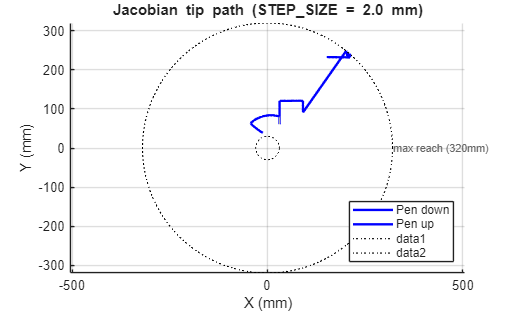

 
%visualization
 
% FK reconstruction for comparison
tip_x = L1*cos(output(:,1)*pi/180) + L2*cos((output(:,1)+output(:,2))*pi/180);
tip_y = L1*sin(output(:,1)*pi/180) + L2*sin((output(:,1)+output(:,2))*pi/180);
 
% tip path
figure(1);
hold on; axis equal; grid on;
title(sprintf('Jacobian tip path (STEP\\_SIZE = %.1f mm)', STEP_SIZE));
xlabel('X (mm)'); ylabel('Y (mm)');
for i = 2:size(output,1)
    if output(i,3) == 1
        plot([tip_x(i-1) tip_x(i)],[tip_y(i-1) tip_y(i)],'b-','LineWidth',1.8);
    else
        plot([tip_x(i-1) tip_x(i)],[tip_y(i-1) tip_y(i)],'--','Color',[0.7 0.7 0.7],'LineWidth',0.8);
    end
end
plot(NaN,NaN,'b-','LineWidth',1.8);
plot(NaN,NaN,'--','Color',[0.7 0.7 0.7]);
legend({'Pen down','Pen up'},'Location','best');
% workspace rings
theta = linspace(0,2*pi,300);
plot((L1+L2)*cos(theta),(L1+L2)*sin(theta),'k:','LineWidth',0.8);
plot(abs(L1-L2)*cos(theta),abs(L1-L2)*sin(theta),'k:','LineWidth',0.8);
text(L1+L2+2, 0, sprintf('max reach (%.0fmm)', L1+L2), 'FontSize', 8, 'Color', [0.4 0.4 0.4]);

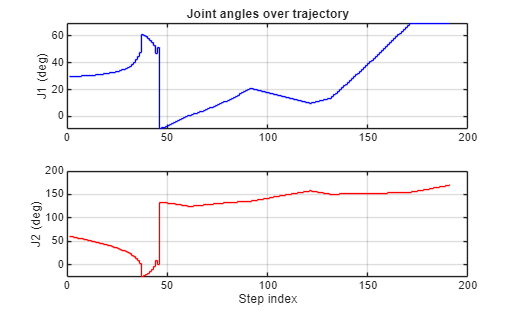

 
% joint angles over time
figure(2);
subplot(2,1,1); stairs(output(:,1),'b'); grid on;
ylabel('J1 (deg)'); title('Joint angles over trajectory');
subplot(2,1,2); stairs(output(:,2),'r'); grid on;
ylabel('J2 (deg)'); xlabel('Step index');

 
%file output
n = size(output, 1);
fid = fopen(OUTPUT_FILE, 'w');
for i = 1:n
    fprintf(fid, '%.4f,%.4f,%d\n', output(i,1), output(i,2), int32(output(i,3)));
end
fclose(fid);
fprintf('Wrote %d rows to %s\n', n, OUTPUT_FILE);

Wrote 191 rows to jacobian_trajectory.csv
